# compare_model2measure_translation_final

clear all
% addpath(genpath('F:/PhD/6DoF_Soft_magnet'));

## Physical model simulation

syms alpha beta gamma Beu_x Beu_y Beu_z x y z v_x v_y v_z w_x w_y w_z k a b c;
syms mu_x mu_y mu_z X Y Z me_x me_y me_z Bus1 Bus2 u0 u;
% x_s y_s z_s x_s2 y_s2 z_s2 x_s3 y_s3 z_s3;

u0=pi*4e-7; %真空中的磁导率  Permeability in  vacuum

a=40;b=16;c=8;%软磁体的三轴长，单位mm; Size of soft magnet, Unit: mm

x_s=200;  y_s=-90;  z_s=-60;
x_s2=200; y_s2=-30; z_s2=-60;
x_s3=200; y_s3=30;  z_s3=-60;
x_s4=200; y_s4=90;  z_s4=-60;     %传感器在世界坐标系中的位置，坐标原点为电磁铁中心  Center of world frame is in the Electromagnet

N=1000;
I=2;
radius=50;  %电磁铁 半径50mm
u1 = N*I*pi*radius*radius;%磁源的磁矩  magnetic moment of magnetic source

C_ZYX=[cos(alpha)*cos(beta), cos(alpha)*sin(beta)*sin(gamma)-sin(alpha)*cos(gamma),  cos(alpha)*sin(beta)*cos(gamma)+sin(alpha)*sin(gamma);
    sin(alpha)*cos(beta), sin(alpha)*sin(beta)*sin(gamma)+cos(alpha)*cos(gamma),  sin(alpha)*sin(beta)*cos(gamma)-cos(alpha)*sin(gamma);
    -sin(beta),           cos(beta)*sin(gamma),                                    cos(beta)*cos(gamma)];      %Z-Y-X moving angle rotation matrix

C_RPY=[cos(alpha)*cos(beta)*cos(gamma)-sin(alpha)*sin(gamma), -cos(alpha)*cos(beta)*sin(gamma)-sin(alpha)*cos(gamma), cos(alpha)*sin(beta);
    sin(alpha)*cos(beta)*cos(gamma)+cos(alpha)*sin(gamma), -sin(alpha)*cos(beta)*sin(gamma)+cos(alpha)*cos(gamma), sin(alpha)*sin(beta);
    -sin(beta)*cos(gamma), sin(beta)*sin(gamma), cos(beta)]; %Z-Y-Z Euler angles rotation matrix

Peu = [x;y;z];
Pes1 = [x_s;y_s;z_s];
Pes2 = [x_s2;y_s2;z_s2];
Pes3 = [x_s3;y_s3;z_s3];
Pes4 = [x_s4;y_s4;z_s4];
Pus1 = Pes1-Peu;
Pus2 = Pes2-Peu;
Pus3 = Pes3-Peu;
Pus4 = Pes4-Peu;

Peulenth = norm(Peu);%sqrt( x^2 + y^2 + z^2 );                 %软磁体位置的向量模长
Peuvec = [x/Peulenth;y/Peulenth;z/Peulenth];          %软磁体位置的方向向量

Pes1lenth = norm(Pes1);%sqrt(x_s^2 + y_s^2 + z_s^2);             %传感器1位置的向量模长
Pesvec1 = [x_s/Pes1lenth;y_s/Pes1lenth;z_s/Pes1lenth];    %传感器位置的方向向量
Puslenth1 = norm(Pus1);
Pusvec1 = Pus1/Puslenth1;

Pes2lenth = norm(Pes2);%sqrt(x_s^2 + y_s^2 + z_s^2);             %传感器2位置的向量模长
Pesvec2 = [x_s2/Pes2lenth;y_s2/Pes2lenth;z_s2/Pes2lenth];    %传感器位置的方向向量
Puslenth2 = norm(Pus2);
Pusvec2 = Pus2/Puslenth2;

Pes3lenth = norm(Pes3);%sqrt(x_s^2 + y_s^2 + z_s^2);             %传感器3位置的向量模长
Pesvec3 = [x_s3/Pes3lenth;y_s3/Pes3lenth;z_s3/Pes3lenth];    %传感器位置的方向向量
Puslenth3 = norm(Pus3);
Pusvec3 = Pus3/Puslenth3;

Pes4lenth = norm(Pes4);%sqrt(x_s^2 + y_s^2 + z_s^2);             %传感器4位置的向量模长
Pesvec4 = [x_s4/Pes4lenth;y_s4/Pes4lenth;z_s4/Pes4lenth];    %传感器位置的方向向量
Puslenth4 = norm(Pus4);
Pusvec4 = Pus4/Puslenth4;

% position vection of four sensors

%me = [me_x;me_y;me_z];      %电磁铁的磁矩
me=[u1*u;0;0];
%Beu = [Beu_x;Beu_y;Beu_z];  %电磁铁在软磁体处的产生的磁场强度
Beu = u0/(4*pi)*(3*dot(me,Peuvec)*Peuvec-me)/Peulenth^3;



%%求软磁体磁化系数  k of the soft magnet

l = b/a; m = c/a;

fna=1/((X+1)^(3/2)*(X+l^2)^(1/2)*(X+m^2)^(1/2));
fnb=1/((Y+1)^(1/2)*(Y+l^2)^(3/2)*(Y+m^2)^(1/2));
fnc=1/((Z+1)^(1/2)*(Z+l^2)^(1/2)*(Z+m^2)^(3/2));

na=l*m/2*int(fna,X,0,+inf);
nb=l*m/2*int(fnb,Y,0,+inf);
nc=l*m/2*int(fnc,Z,0,+inf);

X=-a^2;
Y=-b^2;
Z=-c^2;

k=4/(3*u0)*pi*a*b*c*[1/na,  0,   0;
    0, 1/nb,  0;
    0,   0,  1/nc]; %椭球体磁化系数矩阵

AA=C_ZYX';
mu = C_ZYX * k * AA * Beu;
mu_x = mu(1);
mu_y = mu(2);
mu_z = mu(3); %软磁体受磁化产生的磁场

Bus1 = u0/(4*pi)*(3*dot(mu,Pusvec1)*Pusvec1-mu)/(Puslenth1^3);  %传感器1测量的软磁体磁场
Bus2 = u0/(4*pi)*(3*dot(mu,Pusvec2)*Pusvec2-mu)/(Puslenth2^3);  %传感器2测量的软磁体磁场
Bus3 = u0/(4*pi)*(3*dot(mu,Pusvec3)*Pusvec3-mu)/(Puslenth3^3);  %传感器3测量的软磁体磁场
Bus4 = u0/(4*pi)*(3*dot(mu,Pusvec4)*Pusvec4-mu)/(Puslenth4^3);  %传感器4测量的软磁体磁场

Bes1 = u0/(4*pi)*(3*dot(me,Pesvec1)*Pesvec1-me)/(Pes1lenth^3);  %传感器1测量的电磁铁磁场
Bes2 = u0/(4*pi)*(3*dot(me,Pesvec2)*Pesvec2-me)/(Pes2lenth^3);  %传感器2测量的电磁铁磁场
Bes3 = u0/(4*pi)*(3*dot(me,Pesvec3)*Pesvec3-me)/(Pes3lenth^3);  %传感器3测量的电磁铁磁场
Bes4 = u0/(4*pi)*(3*dot(me,Pesvec4)*Pesvec4-me)/(Pes4lenth^3);  %传感器4测量的电磁铁磁场

B1=Bes1+Bus1;
B2=Bes2+Bus2;
B3=Bes3+Bus3;
B4=Bes4+Bus4;

Bu1=matlabFunction(Bus1);
Bu2=matlabFunction(Bus2);
Bu3=matlabFunction(Bus3);
Bu4=matlabFunction(Bus4);

% Be2=matlabFunction(Bes2);

Bs1=matlabFunction(B1);
Bs2=matlabFunction(B2);
Bs3=matlabFunction(B3);
Bs4=matlabFunction(B4);

## load data

% load("DataTransformation\DataTrans\RM3100Collection\06.28\magdata.mat");
% load("DataTransformation\DataTrans\RM3100Collection\06.28\trdata.mat");
load SimulatonComparison(Experiment_data).mat

magdata=[mag_1S(:,4:6);mag_2S(:,4:6);mag_3S(:,4:6)];

## Correct the background magnetic field


for i1=1:3
    mag_baselinepoint(i1,:)= [mean(magdata(1:50,i1)),mean(magdata(5561:end,i1))];
end

for i1=1:5610
    for j1=1:3
        mag_baseline(i1,j1)=((mag_baselinepoint(j1,2)-mag_baselinepoint(j1,1))/5610)*(i1-1)+mag_baselinepoint(j1,1);
    end
end

for i1=1:5610
    for j1=1:3
    mag_baseline_descend(i1,j1)=abs(mag_baseline(i1,j1)-max(mag_baseline(:,j1)));
    end
end

magdata_correct=magdata+mag_baseline_descend;


trdata=[tr_1S(1:1557,:);tr_2S(:,:);tr_3S(:,:)];
Bground=[57000;-37000;-26000];
u=8e10;

parfor i1=1:size(trdata,1)
    B_simu(i1,:)=Bs2(0,0,0,u,trdata(i1,4),trdata(i1,5),trdata(i1,6))+Bground;
end

Starting parallel pool (parpool) using the 'local' profile ...
Preserving jobs with IDs: 1 because they contain crash dump files.
You can use 'delete(myCluster.Jobs)' to remove all jobs created with profile local. To create 'myCluster' use 'myCluster = parcluster('local')'.
Connected to the parallel pool (number of workers: 14).



B_simu(:,2:3)=-B_simu(:,2:3);

mag_correct1=magdata_correct(1:1557,:);
mag_correct2=magdata_correct(1558:3963,:);
mag_correct3=magdata_correct(3964:end,:);

B_simu_correct1=B_simu(1:1557,:);
B_simu_correct2=B_simu(1558:3963,:);
B_simu_correct3=B_simu(3964:end,:);

## plot figures

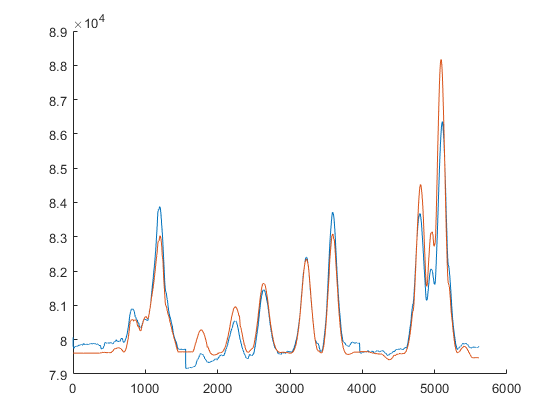


figure();
hold on;
% yyaxis left
plot(magdata_correct(:,2));
% yyaxis right
plot(B_simu(:,1));

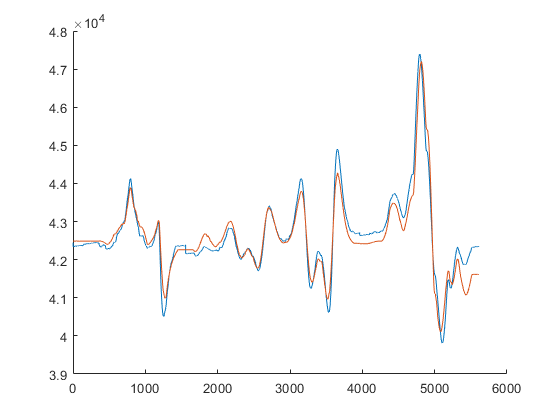


figure();
hold on;
% yyaxis left
plot(magdata_correct(:,1))
% yyaxis right
plot(B_simu(:,2))

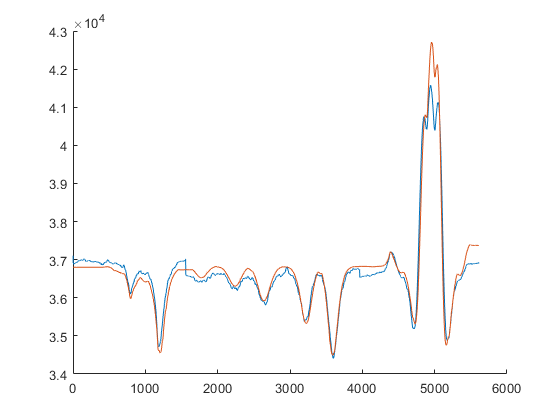


figure();
hold on;
% yyaxis left
plot(magdata_correct(:,3))
% yyaxis right
plot(B_simu(:,3))


[r2t_mx,msetx]=rsquare([B_simu(:,1)/100],[magdata_correct(:,2)/100])

r2t_mx = 0.9110

msetx = 4.2175

[r2t_my,msety]=rsquare([B_simu(:,2)/100],[magdata_correct(:,1)/100])

r2t_my = 0.9045

msety = 3.0446

[r2t_mz,msetz]=rsquare([B_simu(:,3)/100],[magdata_correct(:,3)/100])

r2t_mz = 0.9407

msetz = 2.9600

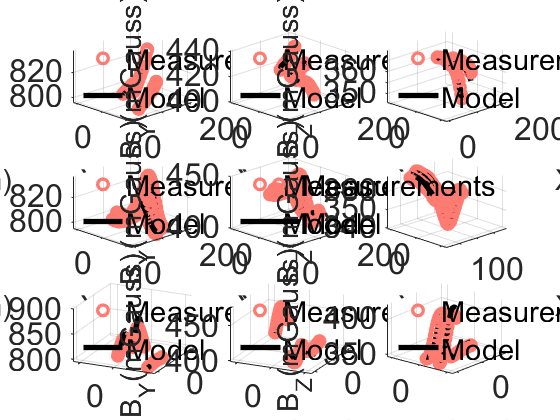

figure()
subplot(3,3,1);
plot3([tr_1S(800:10:940,4);tr_1S(1050:10:1190,4);tr_1S(1280:10:1557,4)],[tr_1S(800:10:940,5); ...
    tr_1S(1050:10:1190,5);tr_1S(1280:10:1557,5)],[magdata_correct(800:10:940,2);magdata_correct(1050:10:1190,2); ...
    magdata_correct(1280:10:1557,2)]/100,'o','MarkerEdgeColor','#FE7B72','MarkerSize',8,'LineWidth',2.5);
hold on;
plot3(tr_1S(800:10:940,4),tr_1S(800:10:940,5),B_simu_correct1(800:10:940,1)/100,'-','LineWidth',4,'Color','black');
plot3(tr_1S(1050:10:1190,4),tr_1S(1050:10:1190,5),B_simu_correct1(1050:10:1190,1)/100,'-','LineWidth',4,'Color','black');
plot3(tr_1S(1280:10:1557,4),tr_1S(1280:10:1557,5),B_simu_correct1(1280:10:1557,1)/100,'-','LineWidth',4,'Color','black');
set(gca,'FontSize',24 );
legend({'Measurements','Model'},'FontSize',22 ,'Location',"northwest",'Orientation',"vertical",'Box',"off");
xlabel('X(mm)','FontSize',22 );
ylabel('Y(mm)','FontSize',22 );
zlabel('B_X(mGauss)','FontSize',22 );
% title('X-axis Translation-Sensor_X','FontSize',24 );
xlim([-10 210]);
ylim([-120 120]);
% zlim([780 880]);
view([-44.2 28.4]);
grid on;

subplot(3,3,2);
plot3([tr_1S(800:10:940,4);tr_1S(1050:10:1190,4);tr_1S(1280:10:1557,4)],[tr_1S(800:10:940,5); ...
    tr_1S(1050:10:1190,5);tr_1S(1280:10:1557,5)],[magdata_correct(800:10:940,1);magdata_correct(1050:10:1190,1); ...
    magdata_correct(1280:10:1557,1)]/100,'o','MarkerEdgeColor','#FE7B72','MarkerSize',8,'LineWidth',2.5);
hold on;
plot3(tr_1S(800:10:940,4),tr_1S(800:10:940,5),B_simu_correct1(800:10:940,2)/100,'-','LineWidth',4,'Color','black');
plot3(tr_1S(1050:10:1190,4),tr_1S(1050:10:1190,5),B_simu_correct1(1050:10:1190,2)/100,'-','LineWidth',4,'Color','black');
plot3(tr_1S(1280:10:1557,4),tr_1S(1280:10:1557,5),B_simu_correct1(1280:10:1557,2)/100,'-','LineWidth',4,'Color','black');
set(gca,'FontSize',24 );
legend({'Measurements','Model'},'FontSize',22 ,'Location',"northwest",'Orientation',"vertical",'Box',"off");
xlabel('X(mm)','FontSize',22 );
ylabel('Y(mm)','FontSize',22 );
zlabel('B_Y(mGauss)','FontSize',22 );
% title('X-Axis-Translation-Sensor_Y','FontSize',24 );
xlim([-10 210]);
ylim([-120 120]);
view([-44.2 28.4]);
grid on;

subplot(3,3,3);
plot3([tr_1S(800:10:940,4);tr_1S(1050:10:1190,4);tr_1S(1280:10:1557,4)],[tr_1S(800:10:940,5); ...
    tr_1S(1050:10:1190,5);tr_1S(1280:10:1557,5)],[magdata_correct(800:10:940,3);magdata_correct(1050:10:1190,3); ...
    magdata_correct(1280:10:1557,3)]/100,'o','MarkerEdgeColor','#FE7B72','MarkerSize',8,'LineWidth',2.5);
hold on;
plot3(tr_1S(800:10:940,4),tr_1S(800:10:940,5),B_simu_correct1(800:10:940,3)/100,'-','LineWidth',4,'Color','black');
plot3(tr_1S(1050:10:1190,4),tr_1S(1050:10:1190,5),B_simu_correct1(1050:10:1190,3)/100,'-','LineWidth',4,'Color','black');
plot3(tr_1S(1280:10:1557,4),tr_1S(1280:10:1557,5),B_simu_correct1(1280:10:1557,3)/100,'-','LineWidth',4,'Color','black');
set(gca,'FontSize',24 );
legend({'Measurements','Model'},'FontSize',22 ,'Location',"northwest",'Orientation',"vertical",'Box',"off");
xlabel('X(mm)','FontSize',22 );
ylabel('Y(mm)','FontSize',22 );
zlabel('B_Z(mGauss)','FontSize',22 );
% title('X-Axis-Translation-Sensor_Z','FontSize',24 );
xlim([-10 210]);
ylim([-120 120]);
view([-44.2 28.4]);
grid on;

subplot(3,3,4);
plot3([tr_2S(920:10:1340,4);tr_2S(1390:10:1825,4);tr_2S(1910:10:end,4)],[tr_2S(920:10:1340,5); ...
    tr_2S(1390:10:1825,5);tr_2S(1910:10:end,5)],[mag_correct2(920:10:1340,2);mag_correct2(1390:10:1825,2); ...
    mag_correct2(1910:10:end,2)]/100,'o','MarkerEdgeColor','#FE7B72','MarkerSize',8,'LineWidth',2.5);
hold on;
plot3(tr_2S(920:10:1340,4),tr_2S(920:10:1340,5),B_simu_correct2(920:10:1340,1)/100,'-','LineWidth',4,'Color','black');
plot3(tr_2S(1390:10:1825,4),tr_2S(1390:10:1825,5),B_simu_correct2(1390:10:1825,1)/100,'-','LineWidth',4,'Color','black');
plot3(tr_2S(1910:10:end,4),tr_2S(1910:10:end,5),B_simu_correct2(1910:10:end,1)/100,'-','LineWidth',4,'Color','black');
set(gca,'FontSize',24 );
legend({'Measurements','Model'},'FontSize',22 ,'Location',"northwest",'Orientation',"vertical",'Box',"off");
xlabel('X(mm)','FontSize',22 );
ylabel('Y(mm)','FontSize',22 );
zlabel('B_X(mGauss)','FontSize',22 );
% title('Y-Axis-Translation-Sensor_X','FontSize',24 );
xlim([-10 210]);
ylim([-120 120]);
% zlim([780 880]);
view([-44.2 28.4]);
grid on;

subplot(3,3,5);

hold on;
plot3([tr_2S(920:10:1340,4);tr_2S(1390:10:1825,4);tr_2S(1910:10:end,4)],[tr_2S(920:10:1340,5); ...
    tr_2S(1390:10:1825,5);tr_2S(1910:10:end,5)],[mag_correct2(920:10:1340,1);mag_correct2(1390:10:1825,1); ...
    mag_correct2(1910:10:end,1)]/100,'o','MarkerEdgeColor','#FE7B72','MarkerSize',8,'LineWidth',2.5);
plot3(tr_2S(920:10:1340,4),tr_2S(920:10:1340,5),B_simu_correct2(920:10:1340,2)/100,'-','LineWidth',4,'Color','black');
plot3(tr_2S(1390:10:1825,4),tr_2S(1390:10:1825,5),B_simu_correct2(1390:10:1825,2)/100,'-','LineWidth',4,'Color','black');
plot3(tr_2S(1910:10:end,4),tr_2S(1910:10:end,5),B_simu_correct2(1910:10:end,2)/100,'-','LineWidth',4,'Color','black');
set(gca,'FontSize',24 );
legend({'Measurements','Model'},'FontSize',22 ,'Location',"northwest",'Orientation',"vertical",'Box',"off");
xlabel('X(mm)','FontSize',22 );
ylabel('Y(mm)','FontSize',22 );
zlabel('B_Y(mGauss)','FontSize',22 );
% title('Y-Axis-Translation-Sensor_Y','FontSize',24 );
xlim([-10 210]);
ylim([-120 120]);
view([-44.2 28.4]);
grid on;

subplot(3,3,6);
hold on;
plot3([tr_2S(920:10:1340,4);tr_2S(1390:10:1825,4);tr_2S(1910:10:end,4)],[tr_2S(920:10:1340,5); ...
    tr_2S(1390:10:1825,5);tr_2S(1910:10:end,5)],[mag_correct2(920:10:1340,3);mag_correct2(1390:10:1825,3); ...
    mag_correct2(1910:10:end,3)]/100,'o','MarkerEdgeColor','#FE7B72','MarkerSize',8,'LineWidth',2.5);
plot3(tr_2S(920:10:1340,4),tr_2S(920:10:1340,5),B_simu_correct2(920:10:1340,3)/100,'-','LineWidth',4,'Color','black');
plot3(tr_2S(1390:10:1825,4),tr_2S(1390:10:1825,5),B_simu_correct2(1390:10:1825,3)/100,'-','LineWidth',4,'Color','black');
plot3(tr_2S(1910:10:end,4),tr_2S(1910:10:end,5),B_simu_correct2(1910:10:end,3)/100,'-','LineWidth',4,'Color','black');
set(gca,'FontSize',24 );
legend({'Measurements','Model'},'FontSize',22 ,'Location',"northeast",'Orientation',"vertical",'Box',"off");
xlabel('X(mm)','FontSize',22 );
ylabel('Y(mm)','FontSize',22 );
zlabel('B_Z(mGauss)','FontSize',22 );
% title('Y-Axis-Translation-Sensor_Z','FontSize',24 );
xlim([60 240]);
ylim([-120 120]);
view([-44.2 28.4]);
grid on;

subplot(3,3,7);
hold on;
plot3([tr_3S(745:10:920,6);tr_3S(1035:10:1210,6);tr_3S(1360:10:end,6)],[tr_3S(745:10:920,5); ...
    tr_3S(1035:10:1210,5);tr_3S(1360:10:end,5)],[mag_correct3(745:10:920,2);mag_correct3(1035:10:1210,2); ...
    mag_correct3(1360:10:end,2)]/100,'o','MarkerEdgeColor','#FE7B72','MarkerSize',8,'LineWidth',2.5);
plot3(tr_3S(745:10:920,6),tr_3S(745:10:920,5),B_simu_correct3(745:10:920,1)/100,'-','LineWidth',4,'Color','black');
plot3(tr_3S(1035:10:1210,6),tr_3S(1035:10:1210,5),B_simu_correct3(1035:10:1210,1)/100,'-','LineWidth',4,'Color','black');
plot3(tr_3S(1360:10:end,6),tr_3S(1360:10:end,5),B_simu_correct3(1360:10:end,1)/100,'-','LineWidth',4,'Color','black');
set(gca,'FontSize',24 );
legend({'Measurements','Model'},'FontSize',22 ,'Location',"northwest",'Orientation',"vertical",'Box',"off");
xlabel('Z(mm)','FontSize',22 );
ylabel('Y(mm)','FontSize',22 );
zlabel('B_X(mGauss)','FontSize',22 );
% title('Z-Axis-Translation-Sensor_X','FontSize',24 );
xlim([-120 100]);
ylim([-120 120]);
% zlim([780 880]);
view([-65 28.4]);
grid on;

subplot(3,3,8);
hold on;
plot3([tr_3S(745:10:920,6);tr_3S(1035:10:1210,6);tr_3S(1360:10:end,6)],[tr_3S(745:10:920,5); ...
    tr_3S(1035:10:1210,5);tr_3S(1360:10:end,5)],[mag_correct3(745:10:920,1);mag_correct3(1035:10:1210,1); ...
    mag_correct3(1360:10:end,1)]/100,'o','MarkerEdgeColor','#FE7B72','MarkerSize',8,'LineWidth',2.5);
plot3(tr_3S(745:10:920,6),tr_3S(745:10:920,5),B_simu_correct3(745:10:920,2)/100,'-','LineWidth',4,'Color','black');
plot3(tr_3S(1035:10:1210,6),tr_3S(1035:10:1210,5),B_simu_correct3(1035:10:1210,2)/100,'-','LineWidth',4,'Color','black');
plot3(tr_3S(1360:10:end,6),tr_3S(1360:10:end,5),B_simu_correct3(1360:10:end,2)/100,'-','LineWidth',4,'Color','black');
set(gca,'FontSize',24 );
legend({'Measurements','Model'},'FontSize',22 ,'Location',"northwest",'Orientation',"vertical",'Box',"off");
xlabel('Z(mm)','FontSize',22 );
ylabel('Y(mm)','FontSize',22 );
zlabel('B_Y(mGauss)','FontSize',22 );
% title('Z-Axis-Translation-Sensor_Y','FontSize',24 );
xlim([-120 100]);
ylim([-120 120]);
view([-65 28.4]);
grid on;

subplot(3,3,9);
hold on;
plot3([tr_3S(745:10:920,6);tr_3S(1035:10:1210,6);tr_3S(1360:10:end,6)],[tr_3S(745:10:920,5); ...
    tr_3S(1035:10:1210,5);tr_3S(1360:10:end,5)],[mag_correct3(745:10:920,3);mag_correct3(1035:10:1210,3); ...
    mag_correct3(1360:10:end,3)]/100,'o','MarkerEdgeColor','#FE7B72','MarkerSize',8,'LineWidth',2.5);
plot3(tr_3S(745:10:920,6),tr_3S(745:10:920,5),B_simu_correct3(745:10:920,3)/100,'-','LineWidth',4,'Color','black');
plot3(tr_3S(1035:10:1210,6),tr_3S(1035:10:1210,5),B_simu_correct3(1035:10:1210,3)/100,'-','LineWidth',4,'Color','black');
plot3(tr_3S(1360:10:end,6),tr_3S(1360:10:end,5),B_simu_correct3(1360:10:end,3)/100,'-','LineWidth',4,'Color','black');
set(gca,'FontSize',24 );
legend({'Measurements','Model'},'FontSize',22 ,'Location',"northwest",'Orientation',"vertical",'Box',"off");
xlabel('Z(mm)','FontSize',22 );
ylabel('Y(mm)','FontSize',22 );
zlabel('B_Z(mGauss)','FontSize',22 );
% title('Z-Axis-Translation-Sensor_Z','FontSize',24 );
xlim([-120 100]);
ylim([-120 120]);
view([-50 28.4]);
grid on;

## amplitude

max([abs(max(B_simu_correct1(:,1)-min(B_simu_correct1(:,1)))), ...
    abs(max(B_simu_correct1(:,2)-min(B_simu_correct1(:,2)))),...
    abs(max(B_simu_correct1(:,3)-min(B_simu_correct1(:,3))))])/100

ans = 34.2317


max([abs(max(B_simu_correct2(:,1)-min(B_simu_correct2(:,1)))), ...
    abs(max(B_simu_correct2(:,2)-min(B_simu_correct2(:,2)))),...
    abs(max(B_simu_correct2(:,3)-min(B_simu_correct2(:,3))))])/100

ans = 35.2957


max([abs(max(B_simu_correct3(:,1)-min(B_simu_correct3(:,1)))), ...
    abs(max(B_simu_correct3(:,2)-min(B_simu_correct3(:,2)))),...
    abs(max(B_simu_correct3(:,3)-min(B_simu_correct3(:,3))))])/100

ans = 87.5179

## R-square

[r2_zx,msezx]=rsquare([B_simu_correct1(:,1)]/100,[mag_correct1(:,2)]/100)

r2_zx = 0.8882

msezx = 2.9173

[r2_zy,msezy]=rsquare([B_simu_correct1(:,2)]/100,[mag_correct1(:,1)]/100)

r2_zy = 0.8676

msezy = 1.8969

[r2_zz,msezz]=rsquare([B_simu_correct1(:,3)]/100,[mag_correct1(:,3)]/100)

r2_zz = 0.8564

msezz = 2.0571

r2_tz=mean([r2_zx,r2_zy,r2_zz])

r2_tz = 0.8707

rmse_tz=mean([sqrt(msezx),sqrt(msezy),sqrt(msezz)])

rmse_tz = 1.5065


[r2_yx,mseyx]=rsquare([B_simu_correct2(:,1)]/100,[mag_correct2(:,2)]/100)

r2_yx = 0.8779

mseyx = 3.0137

[r2_yy,mseyy]=rsquare([B_simu_correct2(:,2)]/100,[mag_correct2(:,1)]/100)

r2_yy = 0.8817

mseyy = 2.1447

[r2_yz,mseyz]=rsquare([B_simu_correct2(:,3)]/100,[mag_correct2(:,3)]/100)

r2_yz = 0.9337

mseyz = 1.3555

r2_ty=mean([r2_yx,r2_yy,r2_yz])

r2_ty = 0.8978

rmse_ty=mean([sqrt(mseyx),sqrt(mseyy),sqrt(mseyz)])

rmse_ty = 1.4549


[r2_xx,msexx]=rsquare([B_simu_correct3(:,1)]/100,[mag_correct3(:,2)]/100)

r2_xx = 0.9161

msexx = 6.2669

[r2_xy,msexy]=rsquare([B_simu_correct3(:,2)]/100,[mag_correct3(:,1)]/100)

r2_xy = 0.9130

msexy = 4.6318

[r2_xz,msexz]=rsquare([B_simu_correct3(:,3)]/100,[mag_correct3(:,3)]/100)

r2_xz = 0.9364

msexz = 4.8124

r2_tx=mean([r2_xx,r2_xy,r2_xz])

r2_tx = 0.9218

rmse_tx=mean([sqrt(msexx),sqrt(msexy),sqrt(msexz)])

rmse_tx = 2.2831